% Initialize SAM model (this may take some time)
sam = segmentAnythingModel;

close all;
boundaryPoints = segmentImageAndExtractBoundaries('Images/test1.jpg',sam);

% Fitting superellipses (n,a,b,angle,h,k)
superellipses = zeros(size(boundaryPoints,1),6);
for i = 1:size(superellipses, 1)
     x = EMS2D((boundaryPoints{i})','OutlierRatio',0);
     superellipses(i,1:2) = x(2:3);
     superellipses(i,3) = x(1);
     superellipses(i,4:5) = x(5:6);
     superellipses(i,6) = x(4);
end
Params = matrix_cell(superellipses);

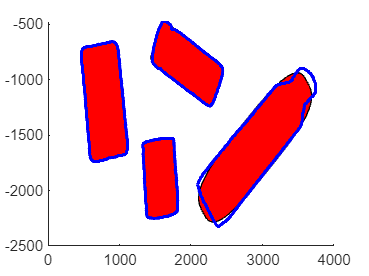

close all
plot_multiple_superellipses(Params)
hold on
% Loop through each boundary found and plot it
for k = 1:length(boundaryPoints)
    boundary = boundaryPoints{k}; % Get the k-th boundary
    plot(boundary(:,1), boundary(:,2), 'b', 'LineWidth', 2); % Overlay boundary on the image
end
hold off

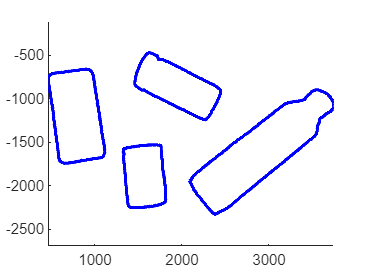


close all;
hold on
axis equal;
% Loop through each boundary found and plot it
for k = 1:length(boundaryPoints)
    boundary = boundaryPoints{k}; % Get the k-th boundary
    plot(boundary(:,1), boundary(:,2), 'b', 'LineWidth', 2); % Overlay boundary on the image
end